Load data:

http://ctnsrv.uwaterloo.ca/vandermeerlab/doku.php?id=analysis:nsb2015:week2

restoredefaultpath; % start with a clean slate
SET_GitHub_root = '/Users/wittkuhn/edu/mind2019/nsb2018/code-matlab/shared'; % replace this with the location of your local GitHub root folder
SET_data_fd = '/Users/wittkuhn/edu/mind2019/R064-2015-04-22'; % replace this with the location of your local data folder
addpath(genpath(cat(2,SET_GitHub_root))); % warning is because this overloads the plot() function

Load the spike and position data:

S = LoadSpikes([]);

LoadSpikes: Loading 110 files...


pos = LoadPos([]); % note, this is raw position data read from the .nvt file, units are "camera pixels"

LoadPos.m: 100.00% of samples tracked.


LoadExpKeys; % see https://github.com/mvdm/vandermeerlab/blob/master/doc/HOWTO_ExpKeys_Metadata.md
LoadMetadata;

Before looking at the data, we will first exclude the pre- and post-run segments of the data:

LoadExpKeys; % annotation file containing some basic information about this data session
S = restrict(S,ExpKeys.TimeOnTrack,ExpKeys.TimeOffTrack); % restrict to on-track data only
pos = restrict(pos,ExpKeys.TimeOnTrack,ExpKeys.TimeOffTrack);

Now we can plot the position data (location of the rat as it runs the maze, in gray), and the position of the rat when an example neuron fired a  spike (in red):

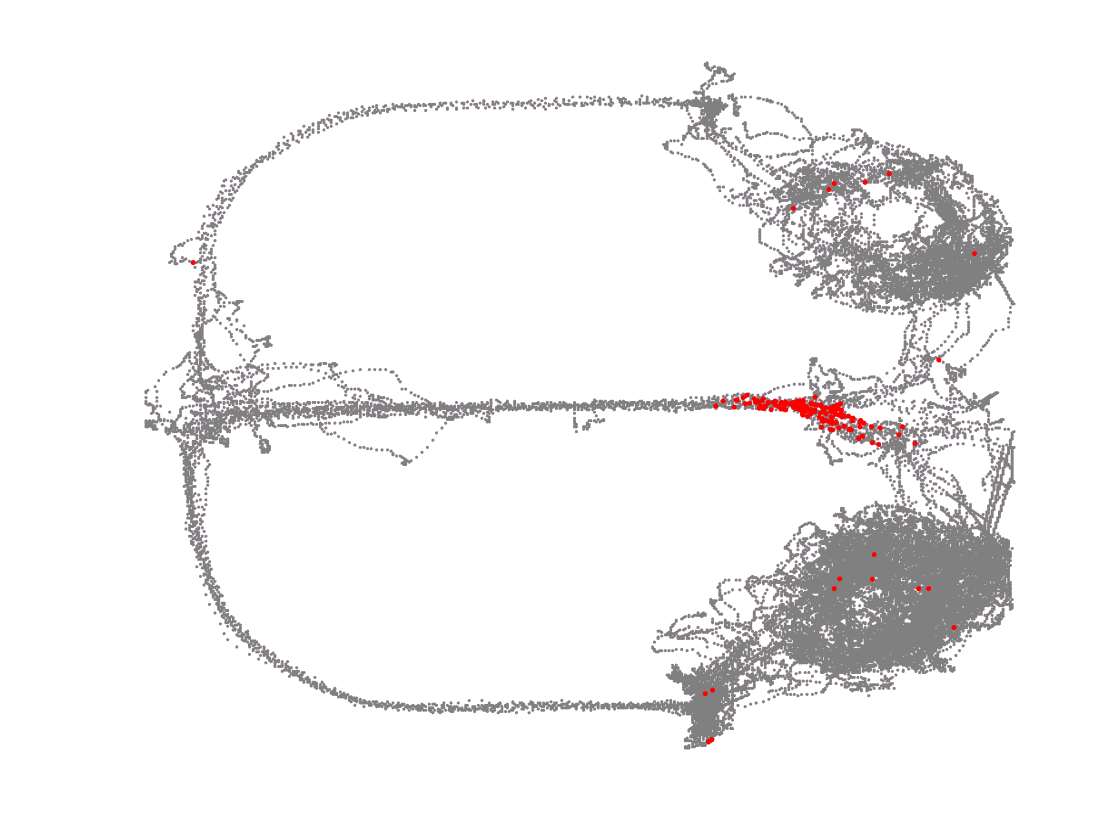

plot(getd(pos,'y'),getd(pos,'x'),'.','Color',[0.5 0.5 0.5],'MarkerSize',1); % note getd() gets data corresponding to a specific label (x and y here)
axis off; hold on;
iC = 7; % select cell 7 (out of 107 total)
spk_x = interp1(pos.tvec,getd(pos,'x'),S.t{iC},'linear');
spk_y = interp1(pos.tvec,getd(pos,'y'),S.t{iC},'linear');
h = plot(spk_y,spk_x,'.r'); axis tight;